# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to November 24th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix 

u = [13 3 5]';
R = Eaa2rotMat(20,u)

R =     0.9899   -0.1084    0.0913
    0.1316    0.9424   -0.3076
   -0.0527    0.3165    0.9471


det(R)

ans = 1

- Compare the transpose and the inverse of the resulting matrix

R'

ans =     0.9899    0.1316   -0.0527
   -0.1084    0.9424    0.3165
    0.0913   -0.3076    0.9471


R^-1

ans =     0.9899    0.1316   -0.0527
   -0.1084    0.9424    0.3165
    0.0913   -0.3076    0.9471


- Using the output matrix, transform a vector parallel to the axis of rotation. 

uPar = u *2;
R * uPar

ans =    26.0000
    6.0000
   10.0000


What happens?

- *Si tenemos el vector inicial normalizado, el determinante resultante siempre será igual a 1, ya que una matri de rotación siempre tiene determinante con valor de 1.*

- *Trasponer la matriz o hacer su inversa equivale en un output igual, esto nos quiere decir que se trata de una Matriz de rotacíón antisimétrica ya que A' = A^-1*

- *Para finalizar si multiplicamos la matriz de rotación por otro vector paralelo al original los valores no se veran alterados, salvo por su magnitud, es como si rotara sobre si mismo y por tanto no cambia las coordenadas.*

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the scalar product between the original vector (the unrotated vector) and the rotated one.

uPerp = [-1 1 2]';
uPerp = uPerp/sqrt(uPerp' * uPerp)

uPerp =    -0.4082
    0.4082
    0.8165


C = dot(u,uPerp) %%Checking perpendicular between u and uPerp equals 0

C = 0

uRotated = R * [-1 1 2]'

uRotated =    -0.9157
    0.1955
    2.2635


C = dot(uPerp,uRotated)

C = 2.3018

DOT = sqrt(uPerp' * uPerp) * sqrt(uRotated' * uRotated)

DOT = 2.4495


C/DOT

ans = 0.9397

acosd(C/DOT)

ans = 20.0000

 What you observe? (Hint: Think about the scalar product definition)

*Si aislamos el ángulo de la fórmula del producto escalar obtenemos el ángulo de rotación inicial.*

*La fórmula del producto escalar nos dice que el resultado es igual al producto de los módulos por el angulo de rotación, por tanto al dividir el resultado del producto escalar del vector perpendicular y su rotado entre el modulo de estos dos vectores, obtenemos que el arcoseno equivale a 20 grados.*

*También observamos que el ángulo de rotación conforme se aproxima 90º más se aproxima a 0 el producto escalar. Esto pasa porque si el ángulo fuera 90 el producto escalar de estos sera equivalente a 0 porque son perpendiculares.*

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5);

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100);

 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

vec = zeros(1,100);
for i=1:1:100
   rotMat = Eaa2rotMat(theta(i),axisM(:,i));
   vec(i) = rotMat(1,1)+rotMat(2,2)+rotMat(3,3);
end

- Make a plot of the vector that you have obtained vs the theta angle. Explain why would you expect this result.

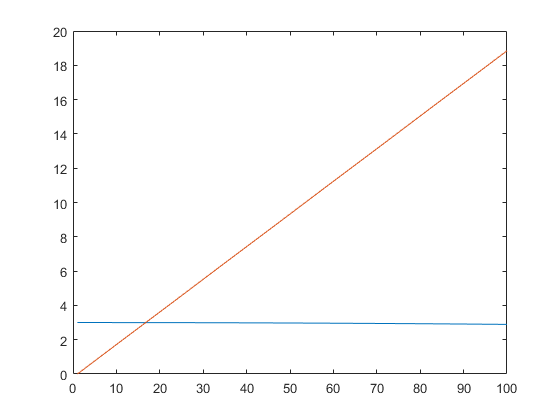


plot(vec)
hold on
plot(theta)
hold off

               * Explanation here*

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : *

## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( , , )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( , , )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( , , )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8


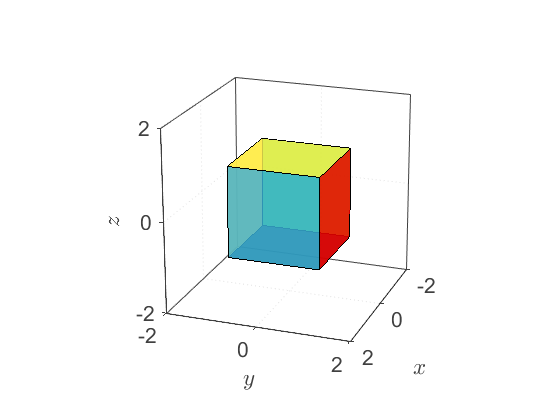

R = eye(3);
M_mod = (R*M')';
Cubeplot(M_mod);

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

- Compare the transpose and the inverse of the resulting matrix

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.